# Example 0: Single stratigraphic case + analysis (3D)

This is a complete introductory example. It shows how to load the appropriate MRST modules, define the inputs according to a given faulted stratigraphy, and generate the output permeability distributions. A comprehensive analysis of the results is also shown. The algorithm is run in 3D mode.

We first make sure that the workspace is clean:

clear
close all force
%rng('default')          % check repeatability

## 1. Load Required MRST Modules

First, navigate to the mrst folder and run `startup.m`. We can then load the appropriate modules for generating MRST grids and upscale the permeability:

mrstModule add mrst-gui coarsegrid upscaling incomp mpfa mimetic
mrstVerbose on     % set to on for more insight in the command window

## 2. Define Model and Upscale Permeability

% 2.1 Mandatory input parameters
% Footwall first and hangingwall next, e.g. {[footwall, FW], [hangingwall, HW]}. 
% We need to define the layer thickness, clay content, layer dip angle, fault 
% dip angle, faulting depth, and burial depth. Further details about input parameter 
% formatting, etc can always be checked from the documentation in the classes 
% and functions.
thickness = {repelem(25, 1, 4), [5 10 15 10 20 10 10 5 15]};                % [m]
vcl       = {[0.1 0.4 0.2 0.5], ...
             [0.3 0.6 0.1 0.7 0.2 0.8 0.3 0.9 0.1]};                        % fraction [-]
dip       = [0, 0];                                                        % [deg.]
faultDip  = 70;                                                             % [deg.]
zf        = [500, 500];                                                     % [FW, HW], [m]
zmax      = {repelem(2000, numel(vcl{1})), repelem(2000, numel(vcl{2}))};   % {FW, HW}
dim       = 3;                    % dimensions (2 = 2D, 3 = 3D)
unit_plot = 'm';

% 2.2 Optional input parameters
% In this case, we indicate a maximum fault material permeability of and a correlation 
% coefficient for dependent variables:
maxPerm = 1000;                 % [mD]
rho     = 0.6;                  % Corr. coeff. for multivariate distributions

% 2.3 Flow upscaling options and number of simulations
U.method          = 'tpfa';     % 'tpfa' for 3D
U.coarseDims      = [1 1 1];    % desired n cells [x, y, z] in coarse grid
U.flexible        = true;       % default true, much faster but U.coarseDims
                                % will be modified in some realizations
                                % unless U.coarseDims = [1 1 1] (do not set
                                % to false in that case).
Nsim              = 1000;       % Number of 3D simulations/realizations

% 2.4 Define Stratigraphy and FaultedSection objects
% Organize the input parameters in HW and FW, and use that info to create a 
% FaultedSection object which contains all required information.
% FW and HW
footwall = Stratigraphy(thickness{1}, vcl{1}, 'Dip', dip(1), ...
                        'DepthFaulting', zf(1), 'DepthBurial', zmax{1});
hangingwall = Stratigraphy(thickness{2}, vcl{2}, 'Dip', dip(2), 'IsHW', 1, ...
                           'NumLayersFW', footwall.NumLayers, ...
                           'DepthFaulting', zf(2), 'DepthBurial', zmax{2});

% Instantiate FaultedSection object (Strati in Faulted Section)
mySect = FaultedSection(footwall, hangingwall, faultDip, 'maxPerm', maxPerm);

% 2.5 Get material distributions
% We use the inputs to constrain the ranges and distributions for each of the 
% intermediate variables.
% Get material property distributions
mySect = mySect.getMatPropDistr();
% Get along-strike segmentation
nSeg = getNSeg(mySect.Vcl, mySect.IsClayVcl, mySect.DepthFaulting);

% 2.6 Generate intermediate variable samples, calculate smear dimensions 
%     and upscale permeability.
% We create two container variables (faults and smears) where we'll save all 
% data for each realization. For each realization, the code defines a Fault object, 
% generates intermediate variable samples, calculates the smear dimensions, and, 
% within upscaleSmearPerm, generates a fault material distribution consistent 
% with the inputs and upscales the permeability.
% Generate fault object with properties for each realization
assert(dim==3);
faultSections = cell(Nsim, 1);
smears = cell(Nsim, 1);
faults = cell(Nsim, 1);
Us = cell(Nsim, 1);
nSeg_fcn = nSeg.fcn;
U_flex = U.flexible;
tstart = tic;
parfor n=1:Nsim    % parfor allowed if you have the parallel computing toolbox
%for n=1
    % Instantiate fault section and get segmentation for this realization
    myFaultSection = Fault2D(mySect, faultDip);
    myFault = Fault3D(myFaultSection, mySect);
    if U_flex
        [myFault, Us{n}] = myFault.getSegmentationLength(U, nSeg_fcn);
    else
        myFault = myFault.getSegmentationLength(U, nSeg_fcn);
    end
    G = [];
    for k=1:numel(myFault.SegLen)
        % Get material property (intermediate variable) samples, and fix
        % fault thickness of current realization (3D only).
        myFaultSection = myFaultSection.getMaterialProperties(mySect, 'corrCoef', rho);
        myFaultSection.MatProps.thick = myFault.Thick;
        if isempty(G)
            G = makeFaultGrid(myFault.Thick, myFault.Disp, ...
                              myFault.Length, myFault.SegLen, U);
        end
        
        % Generate smear object with T, Tap, L, Lmax
        smear = Smear(mySect, myFaultSection, G, 1);
        
        % Place fault materials and assign cell-based properties in 2D section
        myFaultSection = myFaultSection.placeMaterials(mySect, smear, G);
        
        % Extrude 2D section to fill current segment
        myFault = myFault.assignExtrudedVals(G, myFaultSection, k);
        
        % Save results
        faultSections{n}{k} = myFaultSection;
        smears{n}{k} = smear;
    end

    % Compute 3D upscaled permeability distribution
    if U_flex
        myFault = myFault.upscaleProps(G, Us{n});
    else
        myFault = myFault.upscaleProps(G, U);
    end
    
    % Save results
    faults{n} = myFault;
    if mod(n, 50) == 0
        disp(['Simulation ' num2str(n) ' / ' num2str(Nsim) ' completed.'])
    end
end

Simulation 50 / 1000 completed.
Simulation 300 / 1000 completed.
Simulation 450 / 1000 completed.
Simulation 150 / 1000 completed.
Simulation 100 / 1000 completed.
Simulation 250 / 1000 completed.
Simulation 400 / 1000 completed.
Simulation 600 / 1000 completed.
Simulation 550 / 1000 completed.
Simulation 500 / 1000 completed.
Simulation 350 / 1000 completed.
Simulation 200 / 1000 completed.
Simulation 750 / 1000 completed.
Simulation 650 / 1000 completed.
Simulation 800 / 1000 completed.
Simulation 900 / 1000 completed.
Simulation 700 / 1000 completed.
Simulation 850 / 1000 completed.
Simulation 1000 / 1000 completed.
Simulation 950 / 1000 completed.


telapsed = toc(tstart);

## 3. Output Analysis

3.1 Visualize stratigraphy and fault (with thickness corresponding to 1st realization)

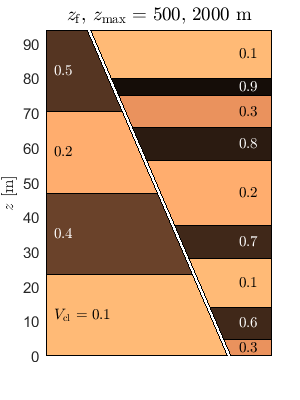

mySect.plotStrati(faults{1}.Thick, faultDip, unit_plot);  

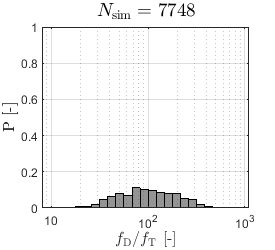

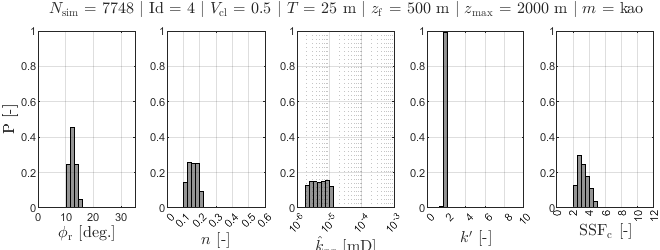

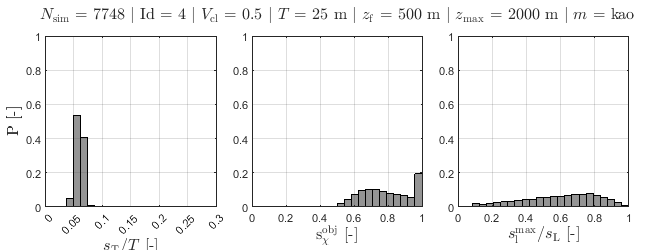


% 3.2 Visualize intermediate variables
% We define a given parent material (id from 1 to n of materials in stratigraphy), 
% and generate histograms and correlation matrix plots.
layerId = 4;                                            
plotMatPropsHist(faultSections, smears, mySect, layerId, dim) 

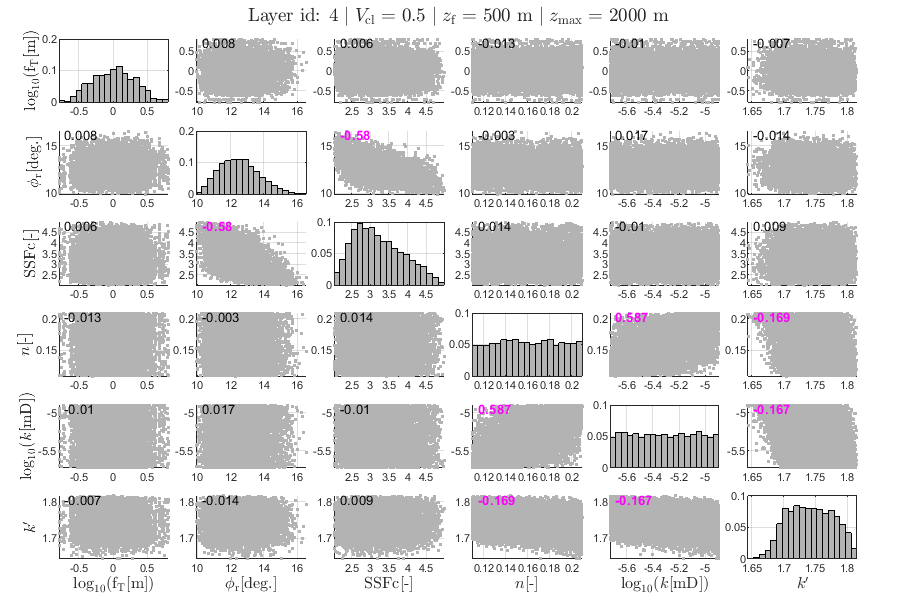

% MatProps correlations
[R, P] = plotMatPropsCorr(faultSections, mySect, layerId, dim);

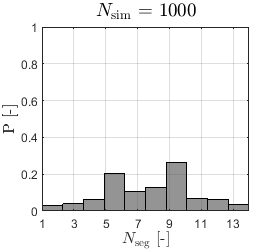

if dim==3
    plotSeg(faults, nSeg)
end

Processing Cells     1 : 20000 of 80000 ... done (0.46 [s], 4.35e+04 cells/second)
Processing Cells 20001 : 40000 of 80000 ... done (0.43 [s], 4.65e+04 cells/second)
Processing Cells 40001 : 60000 of 80000 ... done (0.43 [s], 4.62e+04 cells/second)
Processing Cells 60001 : 80000 of 80000 ... done (0.41 [s], 4.89e+04 cells/second)
Total 3D Geometry Processing Time = 1.791 [s]


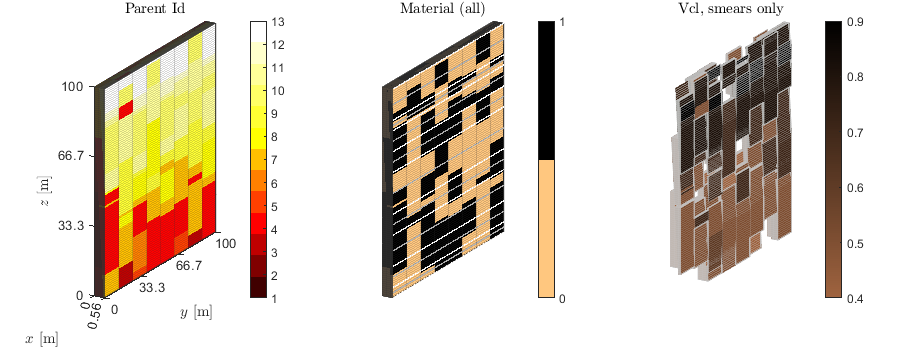

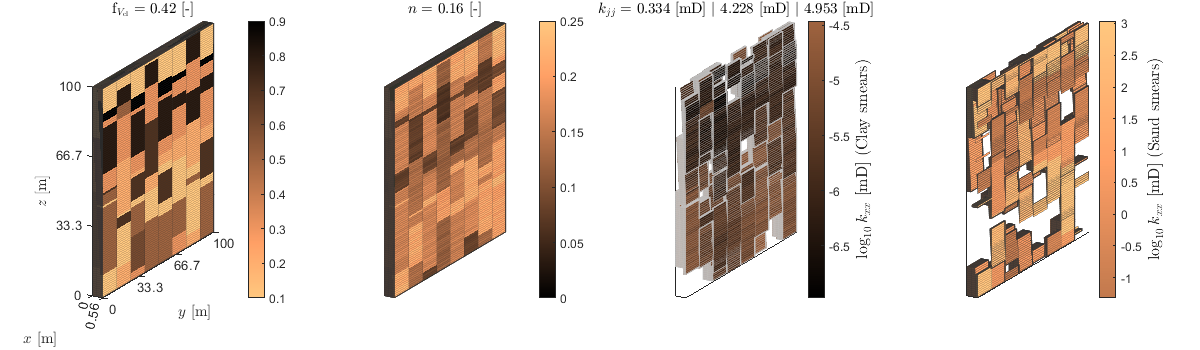

Computing normals, areas, and centroids...	Elapsed time is 0.002964 seconds.
Computing cell volumes and centroids...		Elapsed time is 0.013107 seconds.


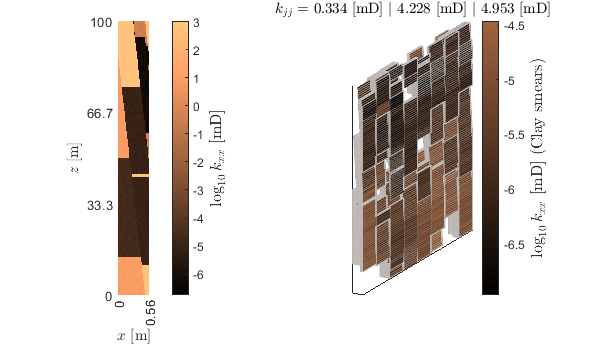


% 3.3 Visualize fault materials
% Visualization for one realization. Choice can be 'randm' (random), 'maxX' 
% (realization with maximum upscaled permeability in across the fault), 'minX', 
% 'maxZ' or 'minZ'.
% General fault materials and perm view
plotId = selectSimId('randm', faults, Nsim);                % simulation index
%plotId = 1;
if U_flex
    faults{plotId}.plotMaterials(faultSections{plotId}{1}, mySect, ...
                                 unit_plot, Us{plotId}) 
else
    faults{plotId}.plotMaterials(faultSections{plotId}{1}, mySect, unit_plot, U) 
end

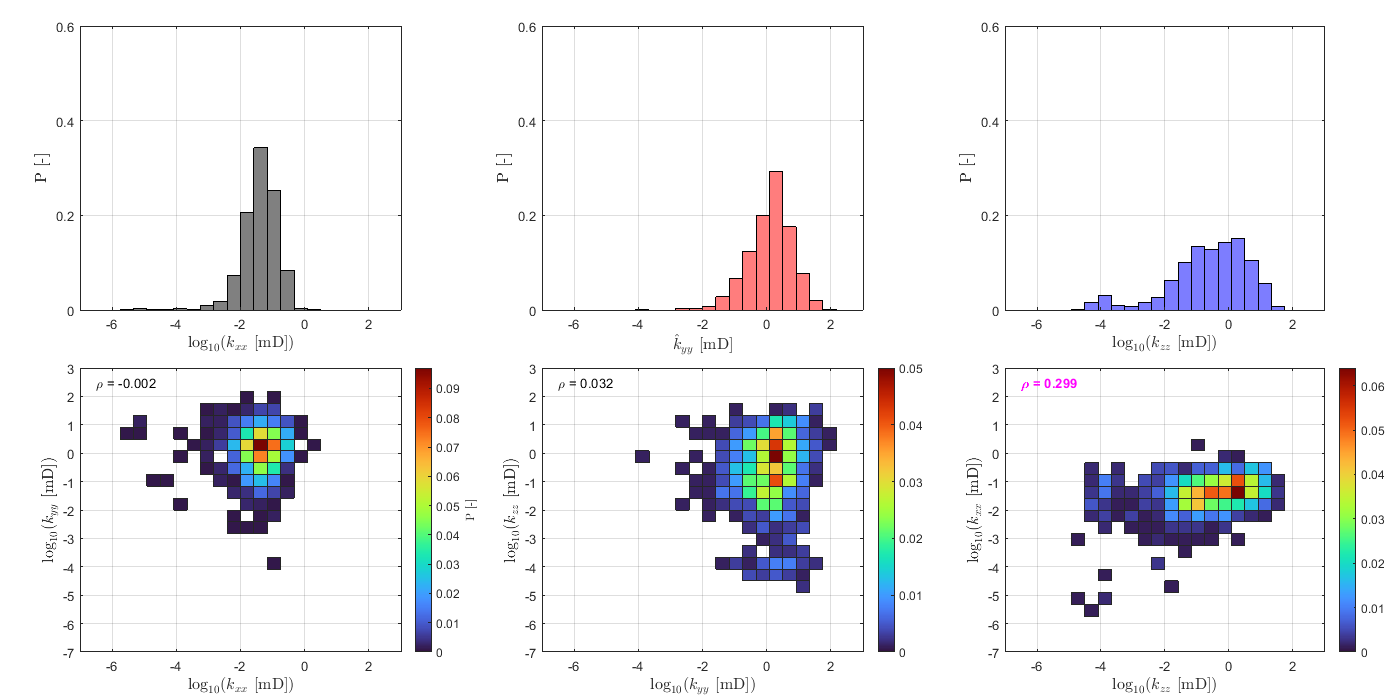


% 3.4. Visualize upscaled permeability
% Plot upscaled permeability distributions (all simulations)
plotUpscaledPerm(faults, dim)